centers =   666.1814  423.1553


Detected Tag ID, Family: 4, tag36h11
  677.7186  441.2611
  679.7950  409.7108
  654.7109  406.1544
  652.5013  435.4949



markerPosition =   677.7186  441.2611    8.0000
  679.7950  409.7108    8.0000
  654.7109  406.1544    8.0000
  652.5013  435.4949    8.0000


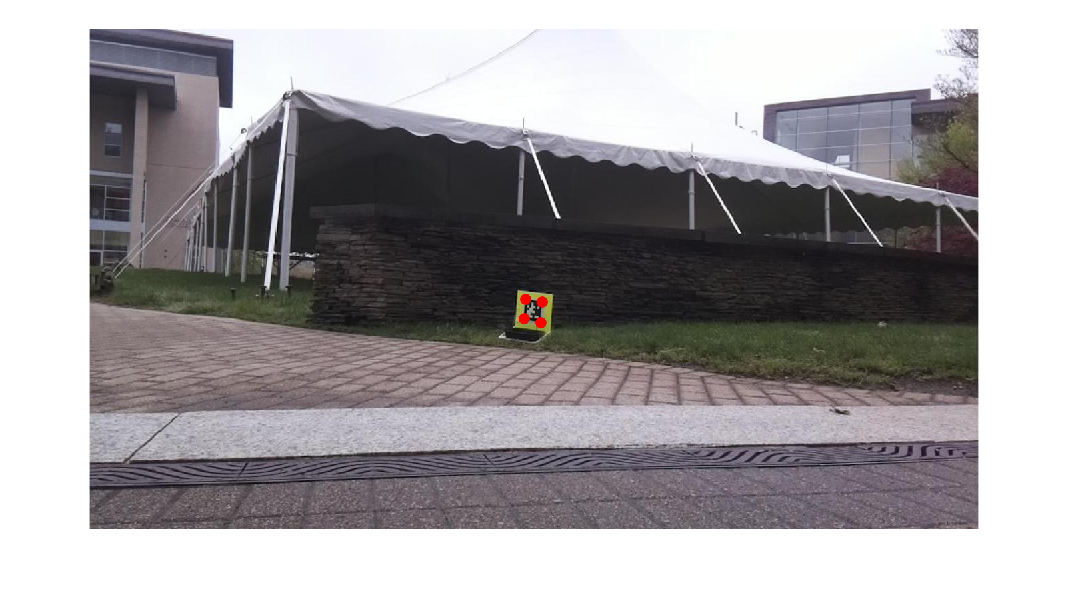

centers =   666.1814  423.1553


ids = 4

I = imread("april_tag_5_5.jpg");
[centers, ids] = detectAprilTags(I, true) % Change to false to suppress output


% I = imread("no_april_tag.jpg");
% [centers, ids] = detectAprilTags(I, true) % Change to false to suppress output


camera_center = 375

ans = 667


% if april tags are found
if isempty(ids)==0
    display("april tags found")
    
    % drive towards april tag
    if checkdirection(centers) == "right"
        %steer to right
        bearing = 5
        DriveRover(robotPi,roverServos,bearing, 0);

    end
    
    % stop when super close
end

    "april tags found"



function [centers, ids] = detectAprilTags(image, display)
    tagFamily = ["tag36h11"];
    
    [ids,loc,detectedFamily] = readAprilTag(image, tagFamily);
    
    centers = zeros(length(ids), 2);
    
    for idx = 1:length(ids)
        % Compute center of tag
        center = mean(loc(:,:,idx));

        % Add 2D center of tag to list
        centers(idx,:) = center;
        
        if display
            % Display the ID and tag family
            disp("Detected Tag ID, Family: " + ids(idx) + ", " ...
                + detectedFamily{idx})
            disp(loc)
            
            % Insert markers to indicate the locations
            markerRadius = 8;
            numCorners = size(loc,1);
            markerPosition = [loc(:,:,idx),repmat(markerRadius,numCorners,1)];
            image = insertShape(image,"FilledCircle",markerPosition,"Color","red","Opacity",1);
            image = insertShape(image,"FilledCircle",markerPosition,"Color","red","Opacity",1);

        end
    end
    
    if display
        imshow(image);
    end
end

function [direction] = checkdirection(apriltag_centroid)
    camera_horizontal_centroid = 1334/2;
    apriltag_horizontal_centroid = apriltag_centroid(1);
    
    % april tag on the left
    if (apriltag_horizontal_centroid < camera_horizontal_centroid)
        direction = "left";

    end
    % april tag on the right
    if (apriltag_horizontal_centroid > camera_horizontal_centroid)
        direction = "right";
    end
end

ACT

function [] = DriveRover(robotPi,roverServos,direction,speed)
    roverServos.setServoPWM(1,direction);    % commands steering servo
    roverServos.setServoPWM(2,speed);    % commands drive speed controller
end